clear; close all

## Regression

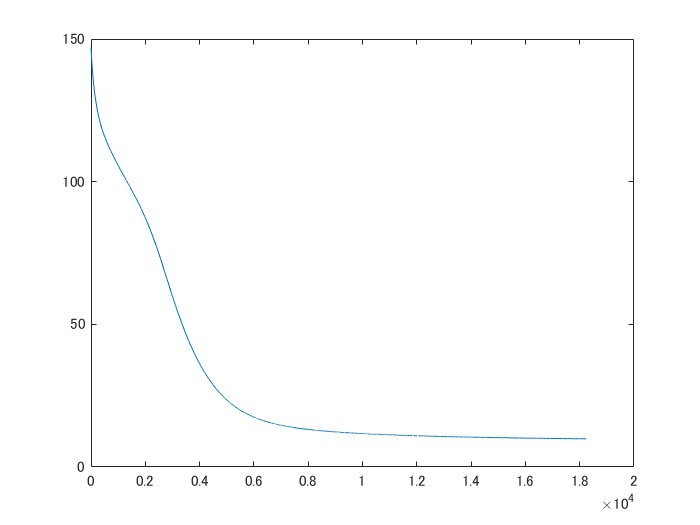

n = 200;
x = linspace(0,2*pi,n);
y = sin(x);

h = [10,6];            % two hidden layers with 10 and 6 neurons
lambda = 1e-2;
[model, L] = mlpReg(x,y,h,lambda);
t = mlpRegPred(model,x);
plot(L);

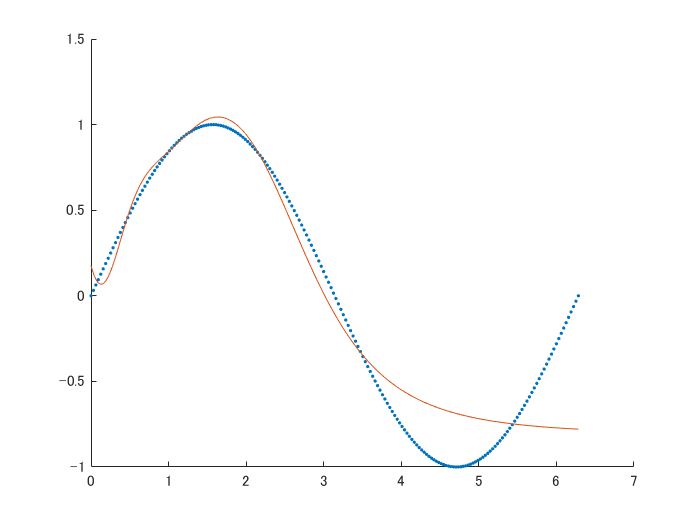

figure;
hold on
plot(x,y,'.');
plot(x,t);
hold off

## Classification

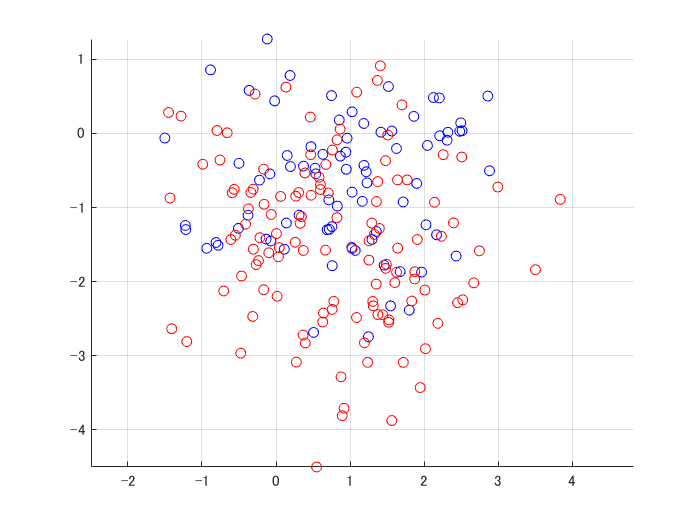

clear;
k = 2;
n = 200;
[X,y] = kmeansRnd(2,k,n);
figure;
plotClass(X,y);

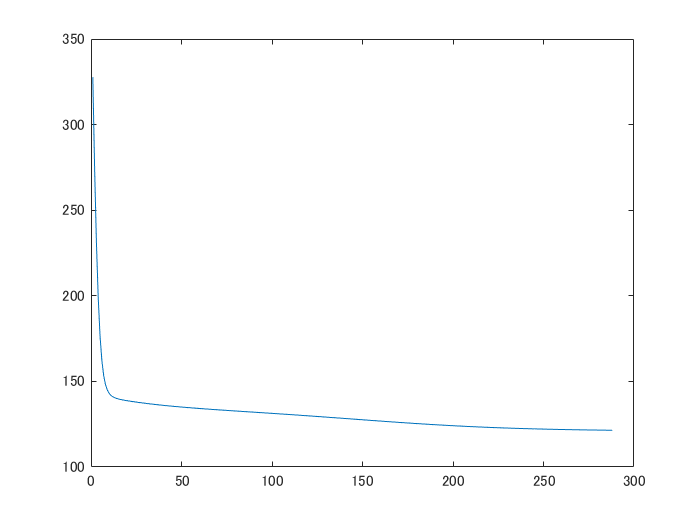


h = 3;
lambda = 1e-2;
[model, llh] = mlpClass(X,y,h,lambda);
[t,p] = mlpClassPred(model,X);
plot(llh);

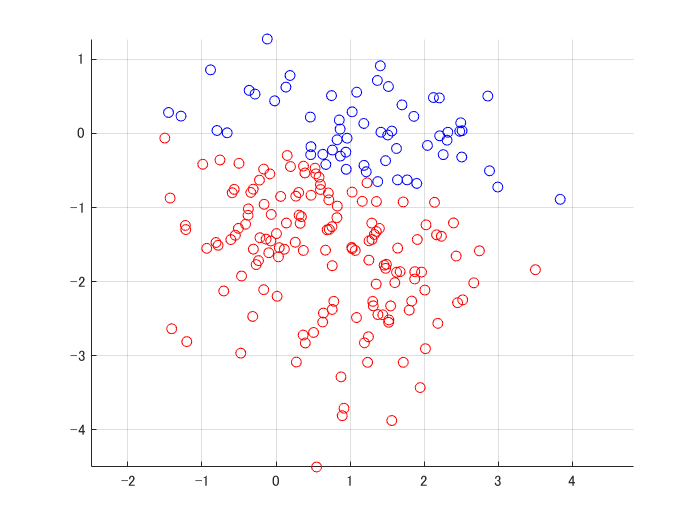

figure;
plotClass(X,t);

figure;